%% 1 2
clear
[y,x] = HW1_sensor(810198479); 
 
y_train = y(1:70);
x_train = x(1:70);
y_test = y(71:100);
x_test = x(71:100);

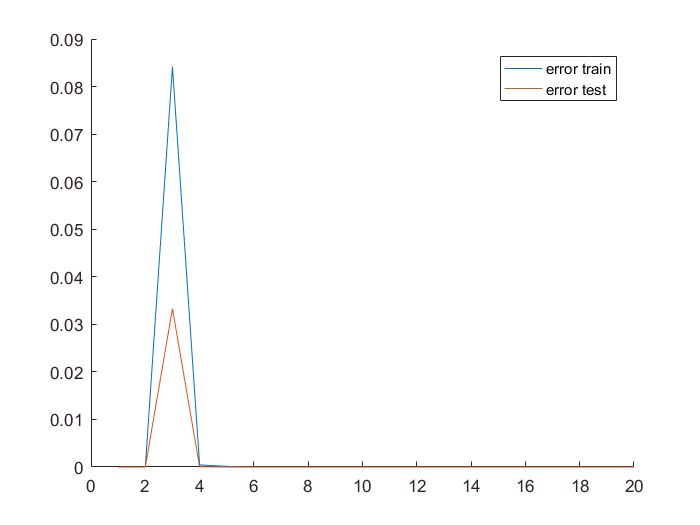

%% 3
x_with_lag = [x; [0, x(1:99)]; [0, 0, 0, x(1:97)] ]; 
x_with_lag_train = x_with_lag(:,1:70); 
x_with_lag_test = x_with_lag(:,71:100); 

max_check_degree = 20; 

for i =1 : max_check_degree 
    y_lag(i,:) = [zeros(1,i), y(1:100-i)]; 
end 
y_with_lag_train = y_lag(:,1:70); 
y_with_lag_test = y_lag(:,71:100);

 
for n_check = 3: max_check_degree 
    phi_train = [x_with_lag_train; y_with_lag_train(1:n_check,:)]; 
    phi_train = phi_train(:,n_check+1:70); 
    y_cut_train = y_train(:,n_check+1:70); 
    theta = (phi_train*phi_train') \ (phi_train * y_cut_train'); 
 
    y_es_by_train = theta' * phi_train; 
    err_train(n_check) = sum((y_es_by_train - y_cut_train).*(y_es_by_train - y_cut_train)); 
 
    phi_test = [x_with_lag_test; y_with_lag_test(1:n_check,:)]; 
    phi_test = phi_test(:,n_check+1:30); 
    y_cut_test = y_test(:,n_check+1:30); 
    y_es_by_test = theta' * phi_test; 
    err_test(n_check) = sum((y_es_by_test - y_cut_test).*(y_es_by_test - y_cut_test)); 
end  
 
hold on 
plot(err_train) 
plot(err_test) 
legend('error train','error test')

%% 4
disp('best theta is 5');

best theta is 5


n_check = 5;
phi_train = [x_with_lag_train; y_with_lag_train(1:n_check,:)]; 
phi_train = phi_train(:,n_check+1:70); 
y_cut_train = y_train(:,n_check+1:70); 
theta = (phi_train*phi_train') \ (phi_train * y_cut_train'); 

disp('b0 =')

b0 =


disp(theta(1))

    1.0999



disp('b1 =')

b1 =


disp(theta(2))

    3.5222



disp('b2 =')

b2 =


disp(theta(3))

   -0.0308



disp('a1 =')

a1 =


disp(-theta(4))

    1.0926



disp('a2 =')

a2 =


disp(-theta(5))

    0.4229



disp('a3 =')

a3 =


disp(-theta(6))

    0.0615



disp('a4 =')

a4 =


disp(-theta(7))

   8.8681e-04



disp('a5 =')

a5 =


disp(-theta(8))

  -7.3032e-04

